% Cleanup!
clear all 
close all
clc

[MotionData]=ParseMatlabApp('1min50hz_nathan_c.mat')

MotionData = struct with fields:
            Accel: [3393×3 double]
      Orientation: [3392×3 double]
           AngVel: [3392×3 double]
          t_Accel: [3393×1 double]
    t_Orientation: [3392×1 double]
         t_AngVel: [3392×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556


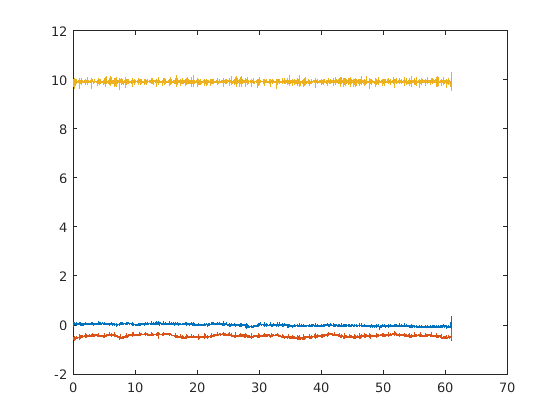

plot(MotionData.t_Accel, MotionData.Accel)

Fs = MotionData.accel_rate % in hertz

Fs = 55.5556

N = length(MotionData.t_Accel)

N = 3393


% FIlter data into 1 minute chunk
chunk_sz = 60 % time in seconds

chunk_sz = 60

chunks = 10

chunks = 10

chunk_sz_index = round(chunk_sz * Fs)

chunk_sz_index = 3333

front_trim = 0 % trim the first ten

front_trim = 0


% Trim the entire front
index_front = round(front_trim * Fs)+1

index_front = 1

MotionData.t_Accel = MotionData.t_Accel(index_front:end)

MotionData = struct with fields:
            Accel: [3393×3 double]
      Orientation: [3392×3 double]
           AngVel: [3392×3 double]
          t_Accel: [3393×1 double]
    t_Orientation: [3392×1 double]
         t_AngVel: [3392×1 double]
       accel_rate: 55.5556
      orient_rate: 55.5556
      AngVel_rate: 55.5556


MotionData.t_Accel = MotionData.t_Accel - MotionData.t_Accel(1);
MotionData.Accel = MotionData.Accel(index_front:end, :);


chunked_Accel = {}


chunked_Accel =

  0×0 empty cell array



chunked_t_Accel = {}


chunked_t_Accel =

  0×0 empty cell array



for i=1:chunks
    begin_splice = (i-1)*chunk_sz_index+1;
    end_splice = (i)*chunk_sz_index;
    if end_splice > length(MotionData.t_Accel)
        break
    end
    % Chunk the data
    chunked_t_Accel{end+1} = MotionData.t_Accel(begin_splice:end_splice);
    chunked_Accel{end+1} = MotionData.Accel(begin_splice:end_splice, :);
    % Take a chunks worht of data
end
%MotionData.t_Accel = MotionData.t_Accel(index_front:index_end)-MotionData.t_Accel(1)
N = length(MotionData.t_Accel)

N = 3393

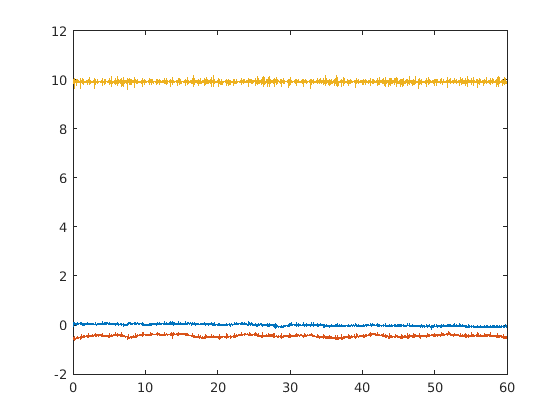

plot(chunked_t_Accel{1}, chunked_Accel{1})

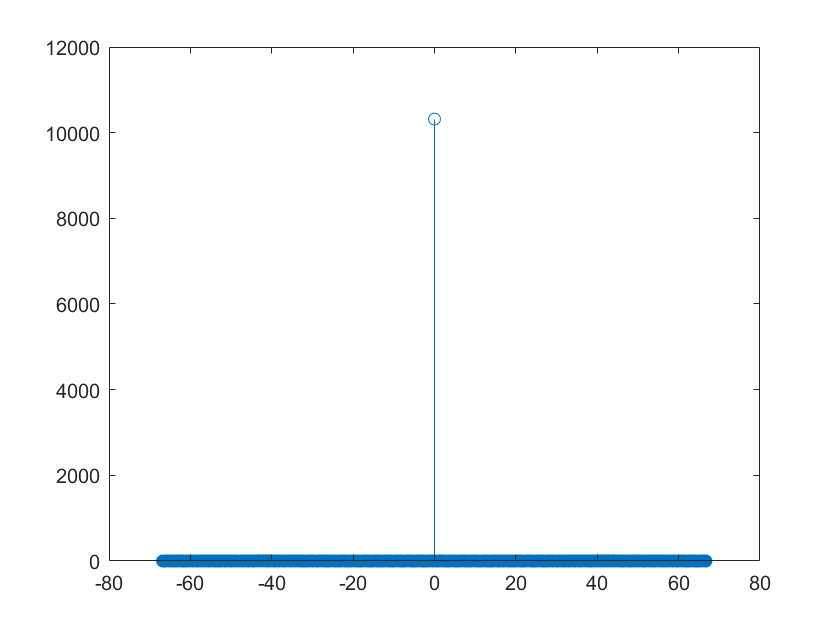

z_fft = fft(MotionData.Accel(:, 3));
z_fft_shift = fftshift(z_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(z_fft_shift))


maxk(abs(z_fft), 5)

ans = 	1.0e+04 *

    1.0317
    0.0004
    0.0004
    0.0004
    0.0004


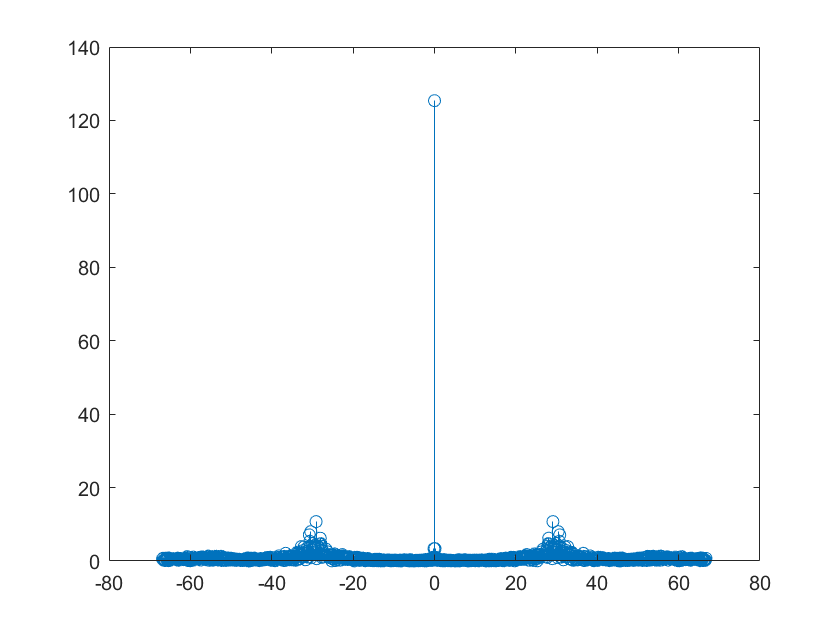

x_fft = fft(MotionData.Accel(:, 1));
x_fft_shift = fftshift(x_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(x_fft_shift))

y_fft = fft(MotionData.Accel(:, 2));
y_fft_shift = abs(fftshift(y_fft));
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

breath_low = 8/60

breath_low = 0.1333

breath_high = 20/60

breath_high = 0.3333

hb_low = 40/60

hb_low = 0.6667

hb_high = 100/60

hb_high = 1.6667

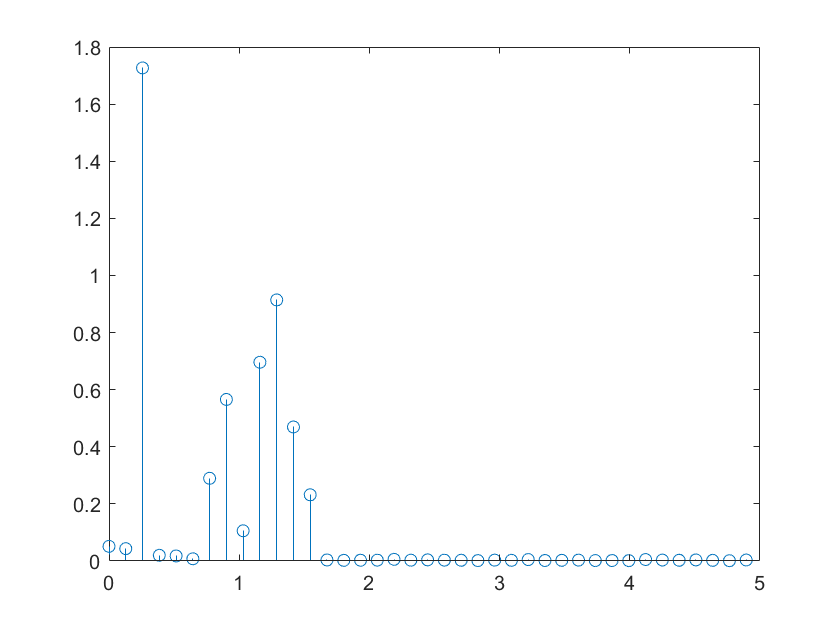


filter_inds = breath_high <= frequencies_shifted & frequencies_shifted <= hb_low | hb_high <= frequencies_shifted | frequencies_shifted <= breath_low;
y_fft_shift(filter_inds) = y_fft_shift(filter_inds)/100;

stem(frequencies_shifted, y_fft_shift)
xlim([0 5])